filepath = "images\starfish_5.jpg"

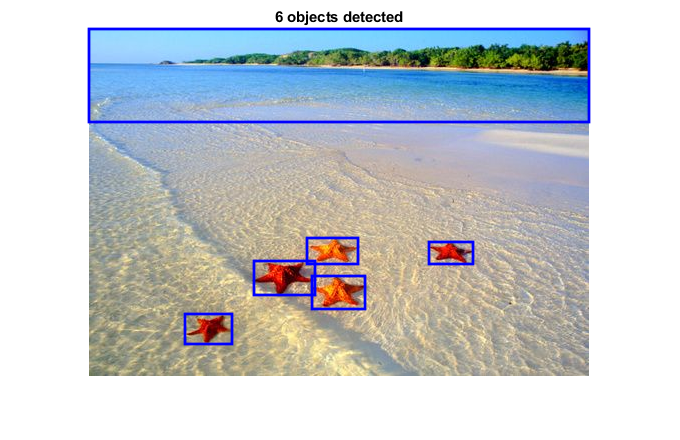

filepath = "images\starfish_17.jpg"

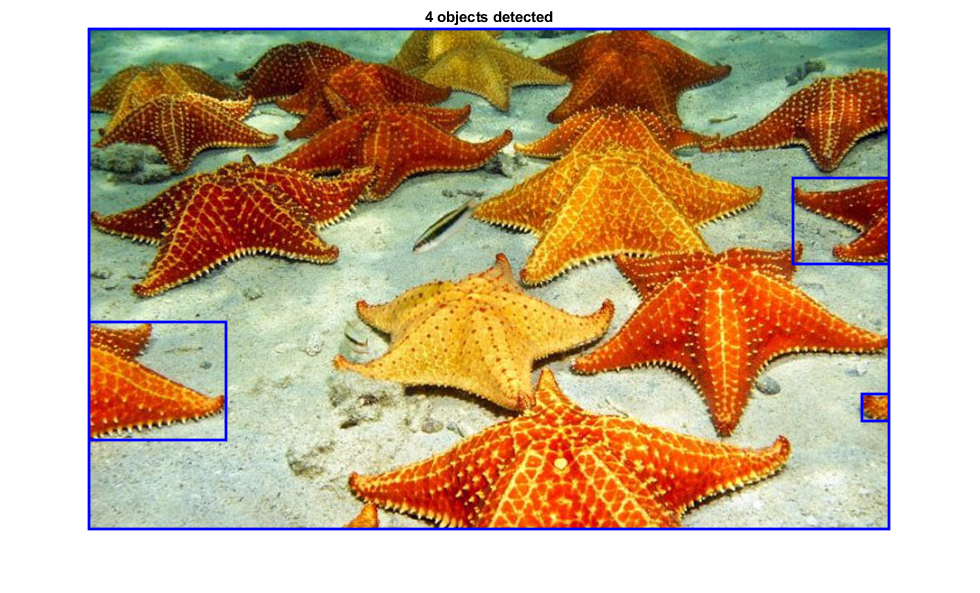

filepath = "images\starfish_overlaid.jpg"

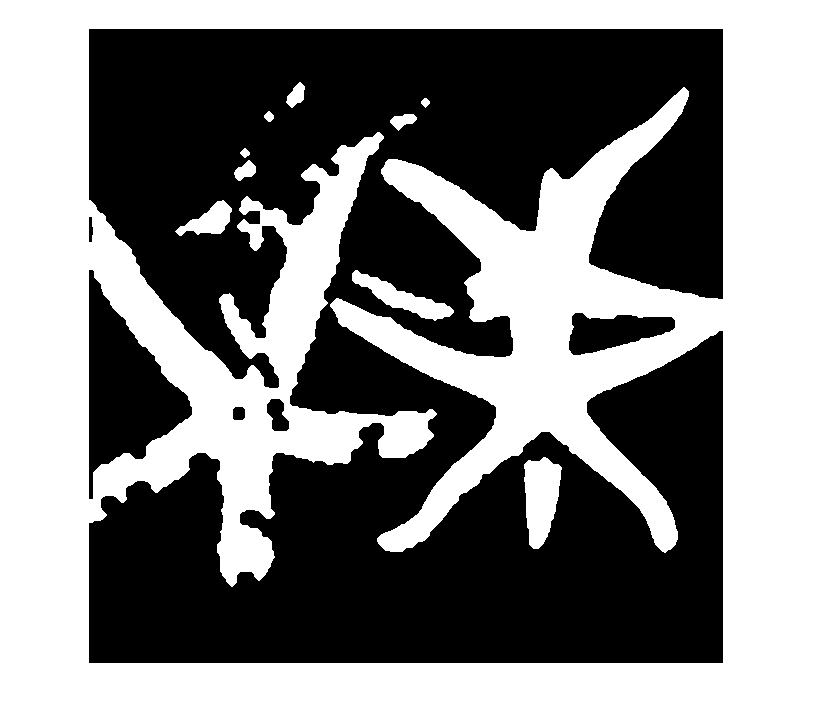

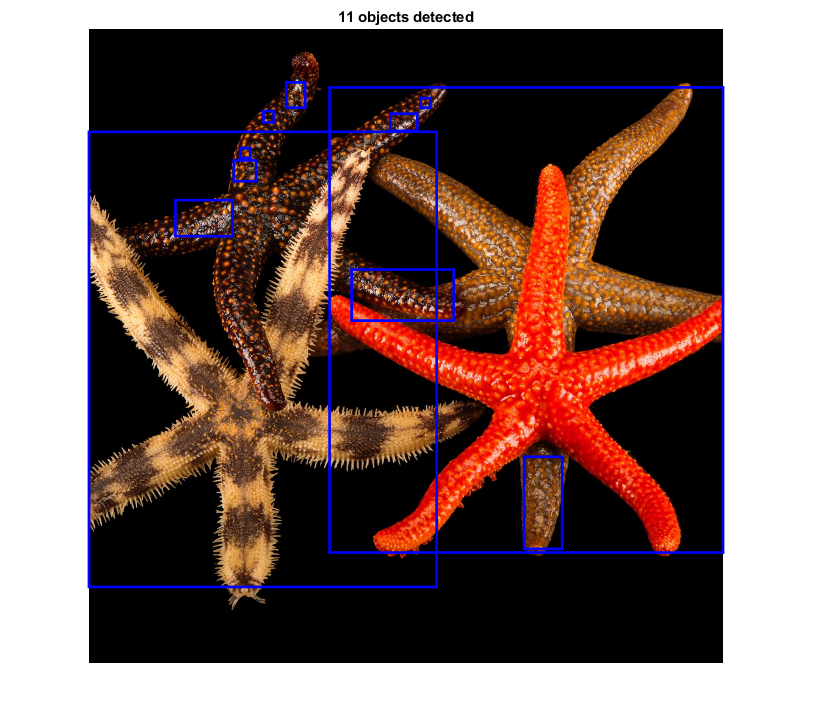

filepath = "images\shellfish_four.jpg"

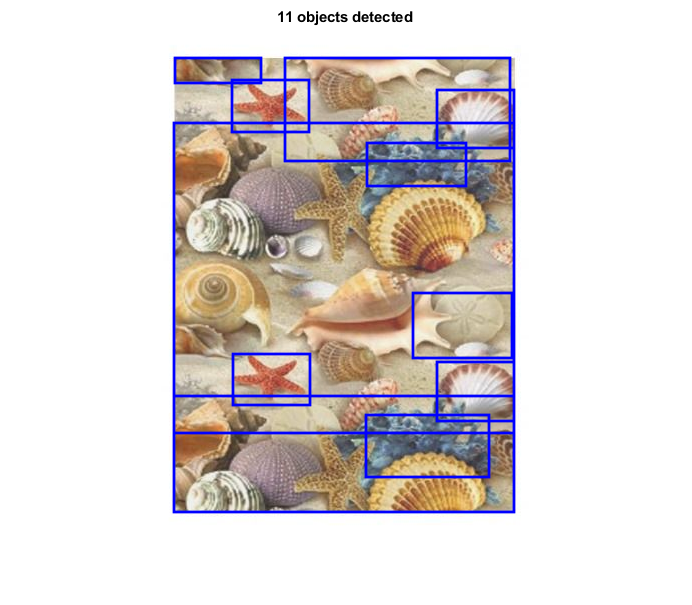

filepath = "images\seashell_five.jpg"

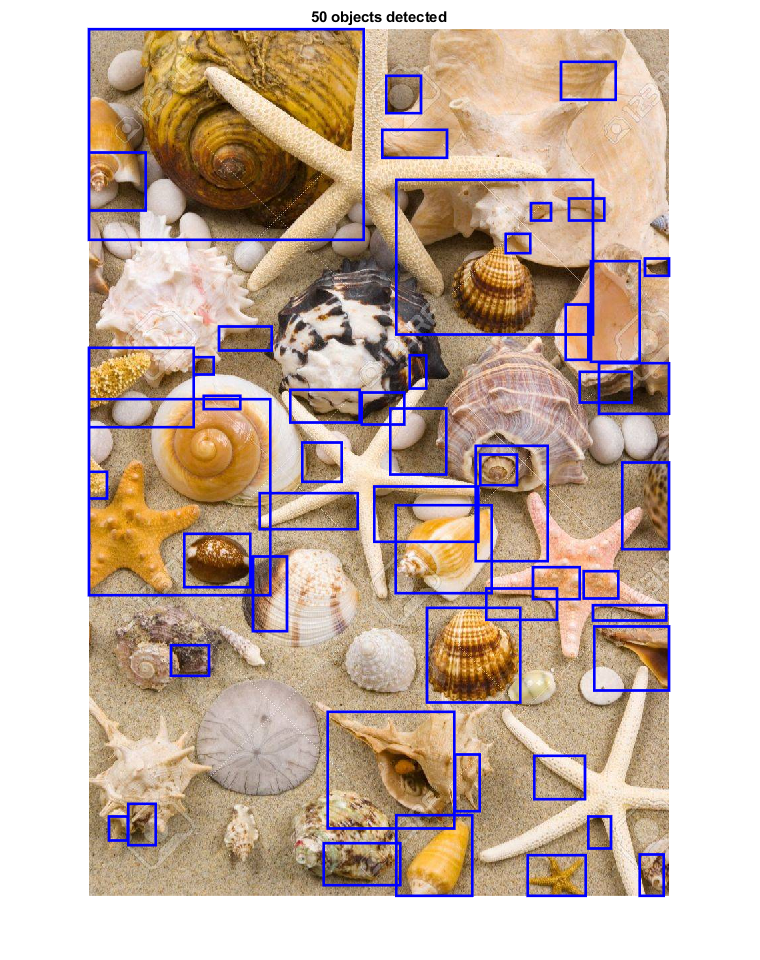

clear
addpath('./functions/');

% files = GetFilesInSubDir("images");
files = ["images\starfish_5.jpg","images\starfish_17.jpg","images\starfish_overlaid.jpg","images\shellfish_four.jpg","images\seashell_five.jpg"];
% files = ["images\starfish_overlaid.jpg"]
for i = 1:numel(files)
    filepath = files(i)
    oim = imread(filepath);
    im = oim;
    
    figure
%     imshow(im);
    
    % Get channel most suited for binarising and blob detection (inital mask).
    [imCh, chN] = GetOptimalChannel(im,true);
    
    % Binarize.
    mask = imbinarize(imCh);
        
    if (IsDark(oim))
        se = strel("diamond", 10);
        mask = imclose(mask, se);
        se = strel("disk", 10);
        mask = imerode(mask, se);
        se = strel("disk", 10);
        
        se = strel("disk", 7);
        mask = imerode(mask, se);
        se = strel("disk", 7);
        mask = imopen(mask, se);
        se = strel("diamond", 7);
        mask = imdilate(mask, se);
        
        se = strel("disk", 5);
        mask = imerode(mask, se);
        se = strel("disk", 10);
        mask = imclose(mask, se);
        se = strel("diamond", 5);
        mask = imdilate(mask, se);
        
        figure
        imshow(mask);
    end
    
    mask = bwareafilt(mask, [400,999999999]);

    % Draw bounding boxes on original image
    figure
    DrawROIs(oim, mask);
end

function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    filepaths = subDir + "\" + {files.name};
end
